We encode the predator--prey equations via an included function called `predprey`, which is found at the end of this file. To solve the IVP we must also provide the initial condition, which is a 2-vector here, and the interval for the independent variable.

u0 = [1; 0.01];
t = linspace(0,80,2001)';       % specify where the time outputs will be
[t,u] = ode45(@predprey,t,u0);

Each row of the output `u` is the value of the solution vector at a single node in time. Each column of `u` is the entire history of one component of the solution.

size_u = size(u)

size_u =         2001           2


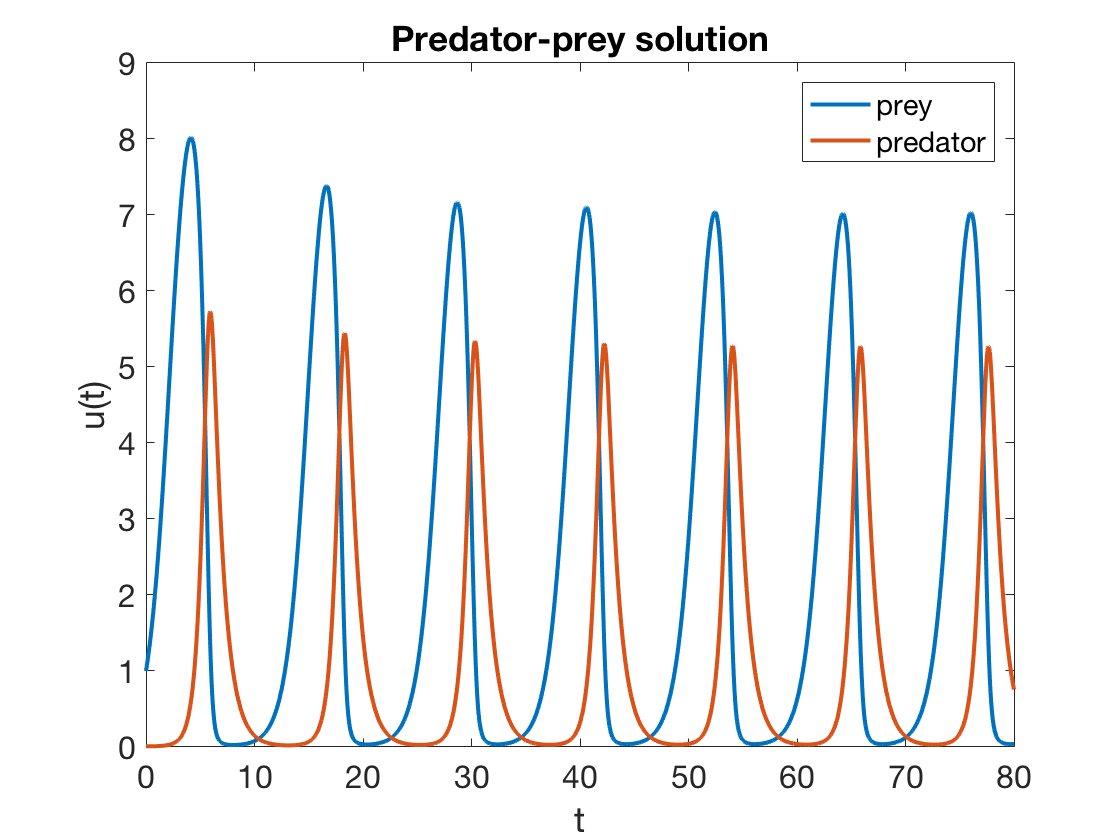

y = u(:,1);  z = u(:,2);  
plot(t,y,t,z)
xlabel('t'), ylabel('u(t)'), title('Predator-prey solution')  % ignore this line
legend('prey','predator')  % ignore this line

When there are just two components, it's common to plot the solution in the *phase plane*, i.e., with $u_1$ and $u_2$ along the axes and time as a parameterization of the curve.

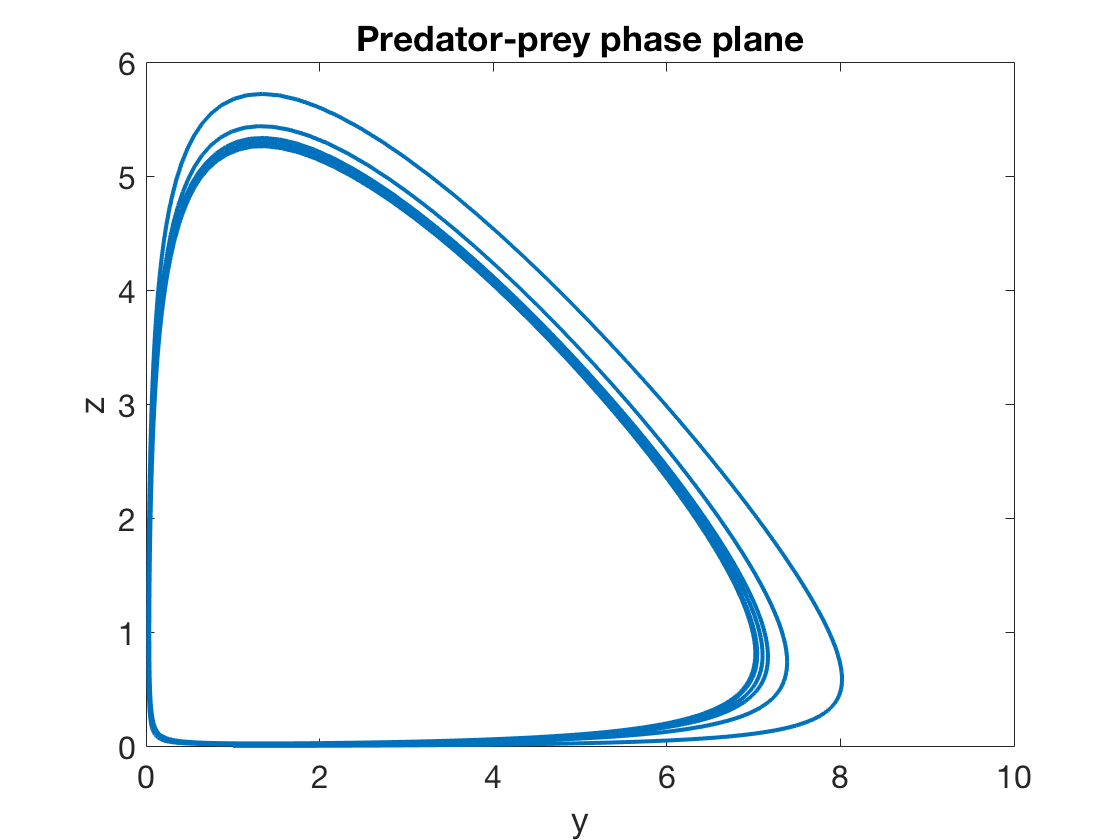

plot(y,z)
xlabel('y'), ylabel('z'), title('Predator-prey phase plane')  % ignore this line

From this plot we can deduce that the solution approaches a periodic one, which in the phase plane is reprepresented by a closed loop. 

Note that the function for the ODE must accept both `t` and `u` inputs, even though there is no explicit dependence on `t`. 

function dudt = predprey(t,u)
    alpha = 0.1;  beta = 0.25;
    y = u(1);  z = u(2);
    s = (y*z) / (1+beta*y);  % appears in both equations
    dudt = [ y*(1-alpha*y) - s;  -z + s ];
end